load("C:\Users\Muriate_C\Desktop\ECE 271A\HW3\hw3Data\TrainingSamplesDCT_subsets_8.mat")
load("C:\Users\Muriate_C\Desktop\ECE 271A\HW3\hw3Data\Alpha.mat")
% load("C:\Users\Muriate_C\Desktop\ECE 271A\HW3\hw3Data\Prior_1.mat") % Strategy 1
% load("C:\Users\Muriate_C\Desktop\ECE 271A\HW3\hw3Data\Prior_2.mat") % Strategy 2

ZigZagPattern = readmatrix("C:\Users\Muriate_C\Desktop\ECE 271A\HW1\Zig-Zag Pattern.txt");
ZigZagPattern = ZigZagPattern + 1;
ZigZagPattern = int8(ZigZagPattern);

img = imread("C:\Users\Muriate_C\Desktop\ECE 271A\HW1\cheetah.bmp");
img = im2double(img);

% Zero Padding
% right = zeros(255, 7);
% bottom = zeros(7, 277);
% img_pad = [[img right]; bottom];
left = zeros(255, 4);
right = zeros(255, 3);
up = zeros(4, 277);
bottom = zeros(3, 277);
img_pad = [up; [left img right]; bottom];

% DCT
img_dct = dct_8(img, img_pad);

% ZigZag Scan
img_scan = blockproc(img_dct, [8 8], @(block_struct) ZigZagScan(block_struct.data, ZigZagPattern));

ground_truth = imread("C:\Users\Muriate_C\Desktop\ECE 271A\HW1\cheetah_mask.bmp");
ground_truth = im2double(ground_truth);

D_BG_all = [D1_BG; D2_BG; D3_BG; D4_BG];
D_BG_index = [0, size(D1_BG, 1), size(D2_BG, 1), size(D3_BG, 1), size(D4_BG, 1)];
D_FG_all = [D1_FG; D2_FG; D3_FG; D4_FG];
D_FG_index = [0, size(D1_FG, 1), size(D2_FG, 1), size(D3_FG, 1), size(D4_FG, 1)];

prob_bg = 0.8000

prob_fg = 0.2000

mean_bg =     2.9316    0.0038   -0.0076   -0.0054    0.0008   -0.0027    0.0008    0.0006   -0.0037   -0.0017   -0.0005   -0.0004   -0.0011   -0.0011   -0.0016    0.0021    0.0024    0.0025    0.0011   -0.0007    0.0002   -0.0011   -0.0006   -0.0006   -0.0007   -0.0005    0.0019   -0.0003   -0.0010    0.0010   -0.0004    0.0006    0.0000   -0.0010    0.0001    0.0002    0.0000   -0.0003   -0.0002   -0.0004    0.0000    0.0005   -0.0001    0.0001    0.0000    0.0003   -0.0007    0.0005   -0.0002   -0.0002


cov_bg =     0.3284   -0.0015    0.0006   -0.0048   -0.0007   -0.0044    0.0006   -0.0009    0.0002   -0.0022   -0.0019    0.0013   -0.0004    0.0009    0.0016    0.0012   -0.0003    0.0010   -0.0011   -0.0004   -0.0001   -0.0002    0.0001    0.0006    0.0002    0.0008    0.0009    0.0004    0.0006   -0.0005    0.0001    0.0006   -0.0001    0.0007   -0.0002   -0.0004   -0.0000    0.0003    0.0003   -0.0004   -0.0004   -0.0001    0.0003    0.0001    0.0005   -0.0002   -0.0002   -0.0002   -0.0000    0.0000
   -0.0015    0.0210   -0.0043   -0.0005    0.0004   -0.0016   -0.0009    0.0010   -0.0019   -0.0008   -0.0001    0.0001    0.0010   -0.0009    0.0002   -0.0004   -0.0005    0.0002   -0.0003   -0.0007    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0002    0.0001    0.0000   -0.0001    0.0001   -0.0001    0.0003    0.0001   -0.0001   -0.0002   -0.0000   -0.0000   -0.0001    0.0002   -0.0003    0.0000   -0.0000   -0.0000    0.0001   -0.0000    0.0002    0.0000   -0.0000   -0.0000

mean_fg =     1.3292    0.0266   -0.0381    0.0088   -0.0177    0.0032    0.0185    0.0046    0.0048    0.0005   -0.0040   -0.0004    0.0056   -0.0114   -0.0095    0.0023    0.0075   -0.0141    0.0081   -0.0003    0.0031    0.0015   -0.0010    0.0039   -0.0040    0.0072    0.0104   -0.0048   -0.0009    0.0017   -0.0072    0.0004    0.0060   -0.0028    0.0021   -0.0019    0.0009    0.0004    0.0014   -0.0024    0.0011   -0.0015   -0.0006    0.0017   -0.0031    0.0003   -0.0003    0.0016    0.0013    0.0001


cov_fg =     0.1918    0.0226   -0.0294    0.0042    0.0076    0.0012    0.0051   -0.0006   -0.0000    0.0045   -0.0020   -0.0055    0.0015    0.0035   -0.0020    0.0026   -0.0024    0.0001   -0.0021   -0.0038    0.0008    0.0007   -0.0011    0.0008    0.0015    0.0035   -0.0012   -0.0014    0.0006    0.0012   -0.0001   -0.0006   -0.0000   -0.0004   -0.0007    0.0004   -0.0000   -0.0005   -0.0003   -0.0010    0.0006   -0.0020    0.0000   -0.0001    0.0012   -0.0006   -0.0003    0.0003   -0.0002    0.0005
    0.0226    0.0460   -0.0185    0.0006    0.0028    0.0031   -0.0047    0.0038   -0.0054    0.0001   -0.0018   -0.0008    0.0002    0.0031    0.0008   -0.0016    0.0014   -0.0006   -0.0002   -0.0011   -0.0010    0.0004   -0.0013    0.0022   -0.0005    0.0020   -0.0002   -0.0014   -0.0004    0.0006    0.0009   -0.0007   -0.0001    0.0003   -0.0011   -0.0002   -0.0001   -0.0001   -0.0001   -0.0003   -0.0006   -0.0003   -0.0001   -0.0001    0.0000    0.0002   -0.0002    0.0005   -0.0000

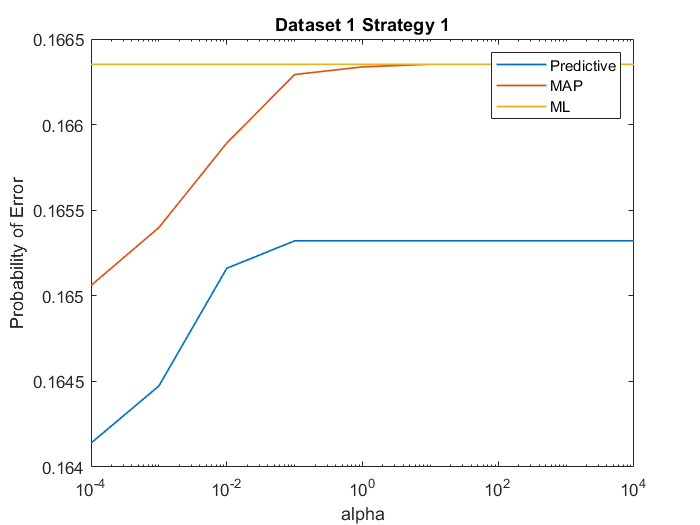

prob_bg = 0.8000

prob_fg = 0.2000

mean_bg =     2.9233   -0.0040    0.0114   -0.0019    0.0017   -0.0031    0.0001   -0.0011    0.0033    0.0019   -0.0008   -0.0015   -0.0011    0.0043   -0.0017    0.0012   -0.0009    0.0013    0.0001    0.0011   -0.0002   -0.0006   -0.0010   -0.0008   -0.0007    0.0002   -0.0002    0.0002    0.0002   -0.0009   -0.0001   -0.0003   -0.0004   -0.0007    0.0001    0.0006   -0.0000   -0.0003   -0.0002    0.0001   -0.0010    0.0009    0.0000    0.0001    0.0006   -0.0007    0.0002   -0.0001   -0.0003   -0.0002


cov_bg =     0.3252    0.0047   -0.0037   -0.0067    0.0022   -0.0051   -0.0018   -0.0024    0.0002   -0.0003   -0.0020   -0.0001   -0.0004   -0.0003   -0.0014    0.0002    0.0002    0.0005    0.0003   -0.0007   -0.0000   -0.0003   -0.0000    0.0001   -0.0001    0.0012    0.0017   -0.0004   -0.0001    0.0001    0.0003    0.0000    0.0006    0.0006   -0.0001   -0.0002    0.0000    0.0002   -0.0001    0.0002   -0.0006   -0.0003    0.0000    0.0000    0.0004   -0.0001   -0.0001   -0.0000    0.0001   -0.0001
    0.0047    0.0200   -0.0030   -0.0003    0.0004   -0.0003   -0.0001    0.0009   -0.0017   -0.0003   -0.0003    0.0002    0.0000   -0.0002    0.0001   -0.0001   -0.0004   -0.0002   -0.0001   -0.0006   -0.0001   -0.0000    0.0000   -0.0002    0.0002    0.0001   -0.0000   -0.0001   -0.0000    0.0001   -0.0001   -0.0000    0.0002   -0.0001   -0.0001   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0002   -0.0001   -0.0000   -0.0000    0.0000    0.0001   -0.0000   -0.0000   -0.0000

mean_fg =     1.2884    0.0460   -0.0151    0.0181   -0.0026    0.0010   -0.0037    0.0075    0.0031    0.0033   -0.0069   -0.0039    0.0002   -0.0013    0.0005    0.0007   -0.0010   -0.0033   -0.0007    0.0052   -0.0016   -0.0022   -0.0022    0.0003    0.0083    0.0050    0.0055    0.0009    0.0019    0.0032   -0.0028    0.0028    0.0044    0.0003   -0.0012   -0.0010    0.0003    0.0010   -0.0025    0.0005   -0.0007   -0.0010    0.0005    0.0006   -0.0025   -0.0006    0.0012    0.0005    0.0010   -0.0005


cov_fg =     0.1744    0.0247   -0.0201    0.0009    0.0091   -0.0032    0.0046    0.0059   -0.0064    0.0058   -0.0035    0.0000   -0.0017    0.0002   -0.0006    0.0014    0.0020   -0.0004   -0.0014   -0.0001   -0.0006    0.0004   -0.0006    0.0006   -0.0004    0.0035    0.0008   -0.0013    0.0001    0.0009   -0.0014    0.0010    0.0010   -0.0002   -0.0009    0.0003   -0.0001   -0.0002    0.0002    0.0001    0.0004   -0.0014   -0.0005   -0.0001    0.0001   -0.0004   -0.0008   -0.0000    0.0001    0.0002
    0.0247    0.0330   -0.0106   -0.0003    0.0010   -0.0007   -0.0012    0.0013   -0.0018    0.0000    0.0004   -0.0001    0.0020   -0.0010    0.0009    0.0003   -0.0004   -0.0002    0.0003   -0.0007    0.0001    0.0003   -0.0003    0.0006    0.0002    0.0011   -0.0004   -0.0003   -0.0003    0.0004   -0.0005    0.0000   -0.0001   -0.0002   -0.0005   -0.0001    0.0000   -0.0000    0.0002   -0.0005   -0.0001   -0.0001   -0.0004    0.0001   -0.0004   -0.0001   -0.0002    0.0001    0.0001

prob_bg = 0.8000

prob_fg = 0.2000

mean_bg =     2.9251   -0.0024    0.0062    0.0018    0.0037   -0.0020    0.0012   -0.0004    0.0004    0.0018    0.0004   -0.0004   -0.0004    0.0019   -0.0008    0.0024    0.0006   -0.0003    0.0016    0.0013    0.0001   -0.0003   -0.0007    0.0005   -0.0009    0.0001   -0.0000    0.0003    0.0001   -0.0005   -0.0005   -0.0011    0.0001   -0.0004    0.0003    0.0004   -0.0001   -0.0003    0.0000   -0.0005    0.0000    0.0005    0.0001    0.0000    0.0002   -0.0006   -0.0004    0.0003   -0.0002    0.0000


cov_bg =     0.3254    0.0049   -0.0024   -0.0075    0.0013   -0.0043   -0.0005    0.0010    0.0003   -0.0009   -0.0028    0.0004    0.0000    0.0000   -0.0010    0.0004   -0.0002    0.0009   -0.0007   -0.0007   -0.0002   -0.0005   -0.0000    0.0000   -0.0002    0.0006    0.0008   -0.0002    0.0001   -0.0004   -0.0001    0.0004    0.0007    0.0001   -0.0001   -0.0001    0.0000    0.0001    0.0000    0.0002   -0.0003   -0.0003    0.0001    0.0000    0.0001    0.0002    0.0000   -0.0001   -0.0001   -0.0000
    0.0049    0.0208   -0.0031   -0.0002    0.0004   -0.0008   -0.0008    0.0009   -0.0025   -0.0004   -0.0001   -0.0000    0.0003   -0.0002   -0.0001   -0.0003   -0.0002    0.0000    0.0001   -0.0006   -0.0001   -0.0000   -0.0000   -0.0000    0.0001    0.0000    0.0001    0.0000   -0.0001   -0.0000   -0.0001   -0.0002    0.0003   -0.0001   -0.0001   -0.0001    0.0000    0.0000   -0.0000   -0.0000    0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0001   -0.0000   -0.0000   -0.0000

mean_fg =     1.2312    0.0435   -0.0372    0.0224   -0.0082    0.0030    0.0026    0.0066    0.0056   -0.0005   -0.0051   -0.0019    0.0026   -0.0003   -0.0034   -0.0038    0.0042   -0.0032   -0.0003    0.0013   -0.0006   -0.0007   -0.0007   -0.0001    0.0022    0.0006    0.0028    0.0008    0.0032    0.0018   -0.0014   -0.0002    0.0033    0.0009    0.0005   -0.0008    0.0005    0.0013   -0.0023    0.0011    0.0010   -0.0010    0.0001    0.0012   -0.0017   -0.0004    0.0008   -0.0008    0.0010   -0.0009


cov_fg =     0.1787    0.0296   -0.0213   -0.0006    0.0066   -0.0044    0.0024    0.0055   -0.0043    0.0014   -0.0024    0.0007   -0.0037   -0.0018   -0.0013    0.0017   -0.0017    0.0021   -0.0012   -0.0004    0.0007    0.0002   -0.0008    0.0010    0.0002    0.0005    0.0000   -0.0006   -0.0004   -0.0005   -0.0010    0.0016    0.0006   -0.0006   -0.0000    0.0002    0.0002   -0.0000    0.0000   -0.0004    0.0007   -0.0009   -0.0001    0.0001    0.0009    0.0001   -0.0004    0.0001   -0.0001    0.0001
    0.0296    0.0521   -0.0097   -0.0015   -0.0003    0.0004   -0.0014    0.0027   -0.0057   -0.0010   -0.0004    0.0011    0.0000   -0.0003    0.0014   -0.0006   -0.0013    0.0012   -0.0006   -0.0006   -0.0001   -0.0000   -0.0002    0.0006   -0.0003    0.0005   -0.0002   -0.0005   -0.0005    0.0001    0.0001    0.0010   -0.0001   -0.0001   -0.0006   -0.0003   -0.0000   -0.0002    0.0001   -0.0007   -0.0005    0.0002    0.0000    0.0004   -0.0000   -0.0000    0.0002    0.0004   -0.0000

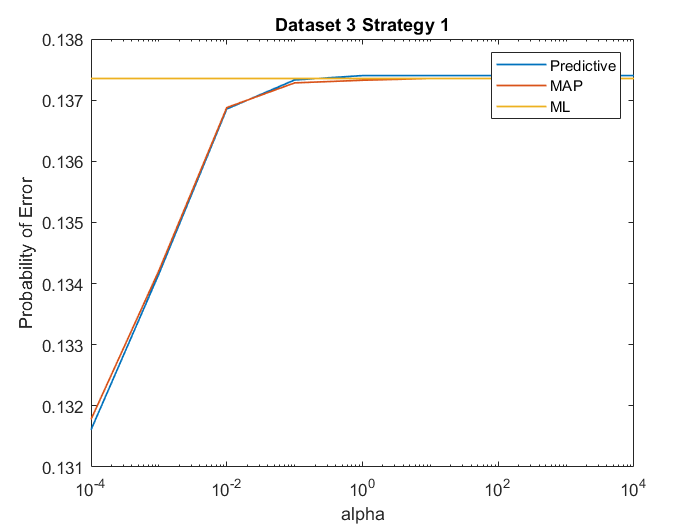

prob_bg = 0.8000

prob_fg = 0.2000

mean_bg =     2.9201    0.0001    0.0044   -0.0009    0.0050   -0.0011    0.0003   -0.0009    0.0008    0.0010   -0.0006   -0.0006   -0.0016    0.0016   -0.0017    0.0017    0.0009    0.0003    0.0014    0.0011   -0.0001   -0.0007   -0.0004   -0.0004   -0.0008   -0.0001    0.0002    0.0004    0.0001   -0.0004   -0.0002   -0.0002   -0.0004   -0.0005    0.0001    0.0004   -0.0001   -0.0004   -0.0004   -0.0002   -0.0003    0.0006   -0.0001    0.0002    0.0003   -0.0001   -0.0004    0.0000   -0.0001   -0.0001


cov_bg =     0.3152    0.0051   -0.0041   -0.0080    0.0007   -0.0055   -0.0005    0.0001    0.0001   -0.0002   -0.0022   -0.0001   -0.0005    0.0006   -0.0006    0.0004   -0.0004    0.0007   -0.0002   -0.0004   -0.0000   -0.0004   -0.0001    0.0001   -0.0002    0.0009    0.0007   -0.0004    0.0002   -0.0002   -0.0002    0.0001    0.0003    0.0002   -0.0000   -0.0001    0.0000    0.0003   -0.0001    0.0002   -0.0001   -0.0001    0.0001    0.0000    0.0001    0.0001    0.0000    0.0000    0.0000   -0.0000
    0.0051    0.0199   -0.0037   -0.0004    0.0003   -0.0005   -0.0008    0.0008   -0.0020   -0.0002   -0.0000   -0.0001    0.0002    0.0000   -0.0001   -0.0002   -0.0003    0.0001   -0.0001   -0.0006   -0.0001    0.0000   -0.0000   -0.0000    0.0001    0.0001    0.0000   -0.0001   -0.0001    0.0001   -0.0001    0.0000    0.0001   -0.0001   -0.0001   -0.0001   -0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0001   -0.0000   -0.0000   -0.0000

mean_fg =     1.2642    0.0306   -0.0368    0.0186   -0.0097   -0.0004    0.0021    0.0161    0.0035   -0.0028   -0.0037   -0.0012    0.0028    0.0014    0.0013   -0.0017    0.0056   -0.0027   -0.0025    0.0004   -0.0006    0.0005   -0.0026    0.0001    0.0037    0.0026    0.0042   -0.0004    0.0021    0.0018   -0.0021   -0.0019    0.0017    0.0010    0.0006   -0.0006   -0.0004    0.0006   -0.0031   -0.0008    0.0008   -0.0001   -0.0011    0.0012   -0.0015   -0.0010    0.0012   -0.0002    0.0001   -0.0007


cov_fg =     0.1675    0.0217   -0.0273    0.0032    0.0019   -0.0018    0.0016    0.0063   -0.0071    0.0024   -0.0010    0.0020   -0.0022   -0.0009   -0.0008    0.0025    0.0001    0.0013   -0.0043    0.0005    0.0003    0.0005   -0.0006    0.0006   -0.0000    0.0006    0.0002   -0.0006   -0.0003   -0.0004   -0.0015    0.0005    0.0007   -0.0003   -0.0006    0.0004    0.0001   -0.0004   -0.0001   -0.0007    0.0004   -0.0011   -0.0006   -0.0001    0.0008   -0.0003   -0.0003   -0.0001    0.0000   -0.0001
    0.0217    0.0451   -0.0103   -0.0001    0.0010   -0.0012   -0.0014    0.0027   -0.0049    0.0001   -0.0008    0.0003    0.0007   -0.0014    0.0009   -0.0005   -0.0007    0.0009   -0.0009   -0.0009   -0.0001    0.0000   -0.0002    0.0009   -0.0000    0.0006   -0.0008   -0.0006   -0.0005    0.0004   -0.0002    0.0009   -0.0003   -0.0003   -0.0009   -0.0001   -0.0001   -0.0002    0.0000   -0.0004   -0.0002   -0.0002   -0.0002    0.0002   -0.0000   -0.0001    0.0000    0.0002   -0.0000

prob_bg = 0.8000

prob_fg = 0.2000

mean_bg =     2.9316    0.0038   -0.0076   -0.0054    0.0008   -0.0027    0.0008    0.0006   -0.0037   -0.0017   -0.0005   -0.0004   -0.0011   -0.0011   -0.0016    0.0021    0.0024    0.0025    0.0011   -0.0007    0.0002   -0.0011   -0.0006   -0.0006   -0.0007   -0.0005    0.0019   -0.0003   -0.0010    0.0010   -0.0004    0.0006    0.0000   -0.0010    0.0001    0.0002    0.0000   -0.0003   -0.0002   -0.0004    0.0000    0.0005   -0.0001    0.0001    0.0000    0.0003   -0.0007    0.0005   -0.0002   -0.0002


cov_bg =     0.3284   -0.0015    0.0006   -0.0048   -0.0007   -0.0044    0.0006   -0.0009    0.0002   -0.0022   -0.0019    0.0013   -0.0004    0.0009    0.0016    0.0012   -0.0003    0.0010   -0.0011   -0.0004   -0.0001   -0.0002    0.0001    0.0006    0.0002    0.0008    0.0009    0.0004    0.0006   -0.0005    0.0001    0.0006   -0.0001    0.0007   -0.0002   -0.0004   -0.0000    0.0003    0.0003   -0.0004   -0.0004   -0.0001    0.0003    0.0001    0.0005   -0.0002   -0.0002   -0.0002   -0.0000    0.0000
   -0.0015    0.0210   -0.0043   -0.0005    0.0004   -0.0016   -0.0009    0.0010   -0.0019   -0.0008   -0.0001    0.0001    0.0010   -0.0009    0.0002   -0.0004   -0.0005    0.0002   -0.0003   -0.0007    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0002    0.0001    0.0000   -0.0001    0.0001   -0.0001    0.0003    0.0001   -0.0001   -0.0002   -0.0000   -0.0000   -0.0001    0.0002   -0.0003    0.0000   -0.0000   -0.0000    0.0001   -0.0000    0.0002    0.0000   -0.0000   -0.0000

mean_fg =     1.3292    0.0266   -0.0381    0.0088   -0.0177    0.0032    0.0185    0.0046    0.0048    0.0005   -0.0040   -0.0004    0.0056   -0.0114   -0.0095    0.0023    0.0075   -0.0141    0.0081   -0.0003    0.0031    0.0015   -0.0010    0.0039   -0.0040    0.0072    0.0104   -0.0048   -0.0009    0.0017   -0.0072    0.0004    0.0060   -0.0028    0.0021   -0.0019    0.0009    0.0004    0.0014   -0.0024    0.0011   -0.0015   -0.0006    0.0017   -0.0031    0.0003   -0.0003    0.0016    0.0013    0.0001


cov_fg =     0.1918    0.0226   -0.0294    0.0042    0.0076    0.0012    0.0051   -0.0006   -0.0000    0.0045   -0.0020   -0.0055    0.0015    0.0035   -0.0020    0.0026   -0.0024    0.0001   -0.0021   -0.0038    0.0008    0.0007   -0.0011    0.0008    0.0015    0.0035   -0.0012   -0.0014    0.0006    0.0012   -0.0001   -0.0006   -0.0000   -0.0004   -0.0007    0.0004   -0.0000   -0.0005   -0.0003   -0.0010    0.0006   -0.0020    0.0000   -0.0001    0.0012   -0.0006   -0.0003    0.0003   -0.0002    0.0005
    0.0226    0.0460   -0.0185    0.0006    0.0028    0.0031   -0.0047    0.0038   -0.0054    0.0001   -0.0018   -0.0008    0.0002    0.0031    0.0008   -0.0016    0.0014   -0.0006   -0.0002   -0.0011   -0.0010    0.0004   -0.0013    0.0022   -0.0005    0.0020   -0.0002   -0.0014   -0.0004    0.0006    0.0009   -0.0007   -0.0001    0.0003   -0.0011   -0.0002   -0.0001   -0.0001   -0.0001   -0.0003   -0.0006   -0.0003   -0.0001   -0.0001    0.0000    0.0002   -0.0002    0.0005   -0.0000

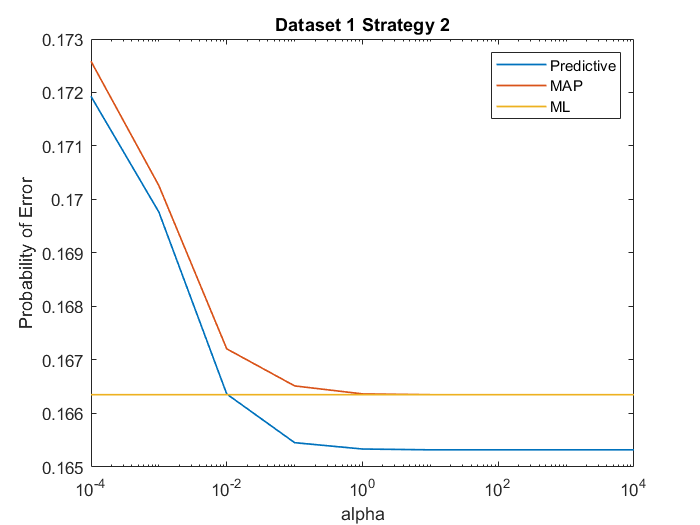

prob_bg = 0.8000

prob_fg = 0.2000

mean_bg =     2.9233   -0.0040    0.0114   -0.0019    0.0017   -0.0031    0.0001   -0.0011    0.0033    0.0019   -0.0008   -0.0015   -0.0011    0.0043   -0.0017    0.0012   -0.0009    0.0013    0.0001    0.0011   -0.0002   -0.0006   -0.0010   -0.0008   -0.0007    0.0002   -0.0002    0.0002    0.0002   -0.0009   -0.0001   -0.0003   -0.0004   -0.0007    0.0001    0.0006   -0.0000   -0.0003   -0.0002    0.0001   -0.0010    0.0009    0.0000    0.0001    0.0006   -0.0007    0.0002   -0.0001   -0.0003   -0.0002


cov_bg =     0.3252    0.0047   -0.0037   -0.0067    0.0022   -0.0051   -0.0018   -0.0024    0.0002   -0.0003   -0.0020   -0.0001   -0.0004   -0.0003   -0.0014    0.0002    0.0002    0.0005    0.0003   -0.0007   -0.0000   -0.0003   -0.0000    0.0001   -0.0001    0.0012    0.0017   -0.0004   -0.0001    0.0001    0.0003    0.0000    0.0006    0.0006   -0.0001   -0.0002    0.0000    0.0002   -0.0001    0.0002   -0.0006   -0.0003    0.0000    0.0000    0.0004   -0.0001   -0.0001   -0.0000    0.0001   -0.0001
    0.0047    0.0200   -0.0030   -0.0003    0.0004   -0.0003   -0.0001    0.0009   -0.0017   -0.0003   -0.0003    0.0002    0.0000   -0.0002    0.0001   -0.0001   -0.0004   -0.0002   -0.0001   -0.0006   -0.0001   -0.0000    0.0000   -0.0002    0.0002    0.0001   -0.0000   -0.0001   -0.0000    0.0001   -0.0001   -0.0000    0.0002   -0.0001   -0.0001   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0002   -0.0001   -0.0000   -0.0000    0.0000    0.0001   -0.0000   -0.0000   -0.0000

mean_fg =     1.2884    0.0460   -0.0151    0.0181   -0.0026    0.0010   -0.0037    0.0075    0.0031    0.0033   -0.0069   -0.0039    0.0002   -0.0013    0.0005    0.0007   -0.0010   -0.0033   -0.0007    0.0052   -0.0016   -0.0022   -0.0022    0.0003    0.0083    0.0050    0.0055    0.0009    0.0019    0.0032   -0.0028    0.0028    0.0044    0.0003   -0.0012   -0.0010    0.0003    0.0010   -0.0025    0.0005   -0.0007   -0.0010    0.0005    0.0006   -0.0025   -0.0006    0.0012    0.0005    0.0010   -0.0005


cov_fg =     0.1744    0.0247   -0.0201    0.0009    0.0091   -0.0032    0.0046    0.0059   -0.0064    0.0058   -0.0035    0.0000   -0.0017    0.0002   -0.0006    0.0014    0.0020   -0.0004   -0.0014   -0.0001   -0.0006    0.0004   -0.0006    0.0006   -0.0004    0.0035    0.0008   -0.0013    0.0001    0.0009   -0.0014    0.0010    0.0010   -0.0002   -0.0009    0.0003   -0.0001   -0.0002    0.0002    0.0001    0.0004   -0.0014   -0.0005   -0.0001    0.0001   -0.0004   -0.0008   -0.0000    0.0001    0.0002
    0.0247    0.0330   -0.0106   -0.0003    0.0010   -0.0007   -0.0012    0.0013   -0.0018    0.0000    0.0004   -0.0001    0.0020   -0.0010    0.0009    0.0003   -0.0004   -0.0002    0.0003   -0.0007    0.0001    0.0003   -0.0003    0.0006    0.0002    0.0011   -0.0004   -0.0003   -0.0003    0.0004   -0.0005    0.0000   -0.0001   -0.0002   -0.0005   -0.0001    0.0000   -0.0000    0.0002   -0.0005   -0.0001   -0.0001   -0.0004    0.0001   -0.0004   -0.0001   -0.0002    0.0001    0.0001

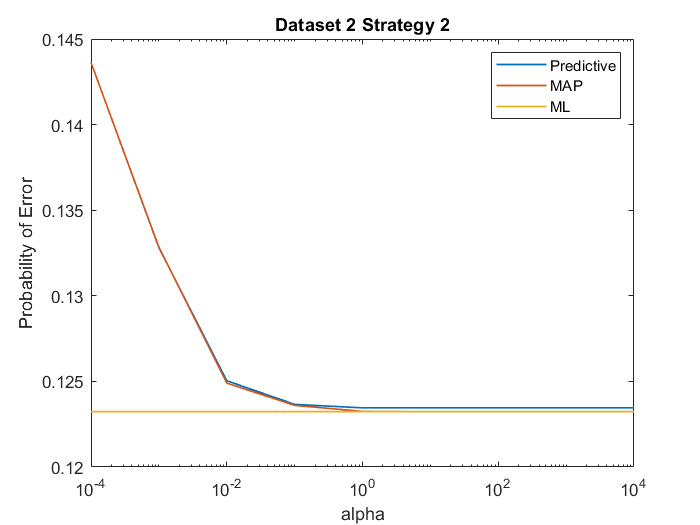

prob_bg = 0.8000

prob_fg = 0.2000

mean_bg =     2.9251   -0.0024    0.0062    0.0018    0.0037   -0.0020    0.0012   -0.0004    0.0004    0.0018    0.0004   -0.0004   -0.0004    0.0019   -0.0008    0.0024    0.0006   -0.0003    0.0016    0.0013    0.0001   -0.0003   -0.0007    0.0005   -0.0009    0.0001   -0.0000    0.0003    0.0001   -0.0005   -0.0005   -0.0011    0.0001   -0.0004    0.0003    0.0004   -0.0001   -0.0003    0.0000   -0.0005    0.0000    0.0005    0.0001    0.0000    0.0002   -0.0006   -0.0004    0.0003   -0.0002    0.0000


cov_bg =     0.3254    0.0049   -0.0024   -0.0075    0.0013   -0.0043   -0.0005    0.0010    0.0003   -0.0009   -0.0028    0.0004    0.0000    0.0000   -0.0010    0.0004   -0.0002    0.0009   -0.0007   -0.0007   -0.0002   -0.0005   -0.0000    0.0000   -0.0002    0.0006    0.0008   -0.0002    0.0001   -0.0004   -0.0001    0.0004    0.0007    0.0001   -0.0001   -0.0001    0.0000    0.0001    0.0000    0.0002   -0.0003   -0.0003    0.0001    0.0000    0.0001    0.0002    0.0000   -0.0001   -0.0001   -0.0000
    0.0049    0.0208   -0.0031   -0.0002    0.0004   -0.0008   -0.0008    0.0009   -0.0025   -0.0004   -0.0001   -0.0000    0.0003   -0.0002   -0.0001   -0.0003   -0.0002    0.0000    0.0001   -0.0006   -0.0001   -0.0000   -0.0000   -0.0000    0.0001    0.0000    0.0001    0.0000   -0.0001   -0.0000   -0.0001   -0.0002    0.0003   -0.0001   -0.0001   -0.0001    0.0000    0.0000   -0.0000   -0.0000    0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0001   -0.0000   -0.0000   -0.0000

mean_fg =     1.2312    0.0435   -0.0372    0.0224   -0.0082    0.0030    0.0026    0.0066    0.0056   -0.0005   -0.0051   -0.0019    0.0026   -0.0003   -0.0034   -0.0038    0.0042   -0.0032   -0.0003    0.0013   -0.0006   -0.0007   -0.0007   -0.0001    0.0022    0.0006    0.0028    0.0008    0.0032    0.0018   -0.0014   -0.0002    0.0033    0.0009    0.0005   -0.0008    0.0005    0.0013   -0.0023    0.0011    0.0010   -0.0010    0.0001    0.0012   -0.0017   -0.0004    0.0008   -0.0008    0.0010   -0.0009


cov_fg =     0.1787    0.0296   -0.0213   -0.0006    0.0066   -0.0044    0.0024    0.0055   -0.0043    0.0014   -0.0024    0.0007   -0.0037   -0.0018   -0.0013    0.0017   -0.0017    0.0021   -0.0012   -0.0004    0.0007    0.0002   -0.0008    0.0010    0.0002    0.0005    0.0000   -0.0006   -0.0004   -0.0005   -0.0010    0.0016    0.0006   -0.0006   -0.0000    0.0002    0.0002   -0.0000    0.0000   -0.0004    0.0007   -0.0009   -0.0001    0.0001    0.0009    0.0001   -0.0004    0.0001   -0.0001    0.0001
    0.0296    0.0521   -0.0097   -0.0015   -0.0003    0.0004   -0.0014    0.0027   -0.0057   -0.0010   -0.0004    0.0011    0.0000   -0.0003    0.0014   -0.0006   -0.0013    0.0012   -0.0006   -0.0006   -0.0001   -0.0000   -0.0002    0.0006   -0.0003    0.0005   -0.0002   -0.0005   -0.0005    0.0001    0.0001    0.0010   -0.0001   -0.0001   -0.0006   -0.0003   -0.0000   -0.0002    0.0001   -0.0007   -0.0005    0.0002    0.0000    0.0004   -0.0000   -0.0000    0.0002    0.0004   -0.0000

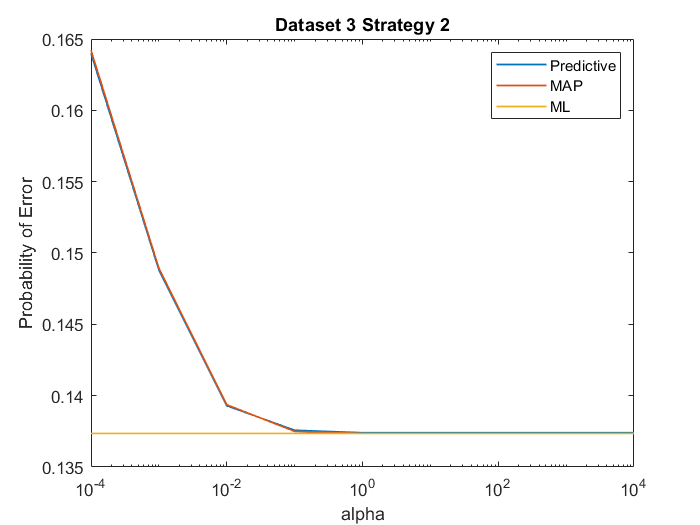

prob_bg = 0.8000

prob_fg = 0.2000

mean_bg =     2.9201    0.0001    0.0044   -0.0009    0.0050   -0.0011    0.0003   -0.0009    0.0008    0.0010   -0.0006   -0.0006   -0.0016    0.0016   -0.0017    0.0017    0.0009    0.0003    0.0014    0.0011   -0.0001   -0.0007   -0.0004   -0.0004   -0.0008   -0.0001    0.0002    0.0004    0.0001   -0.0004   -0.0002   -0.0002   -0.0004   -0.0005    0.0001    0.0004   -0.0001   -0.0004   -0.0004   -0.0002   -0.0003    0.0006   -0.0001    0.0002    0.0003   -0.0001   -0.0004    0.0000   -0.0001   -0.0001


cov_bg =     0.3152    0.0051   -0.0041   -0.0080    0.0007   -0.0055   -0.0005    0.0001    0.0001   -0.0002   -0.0022   -0.0001   -0.0005    0.0006   -0.0006    0.0004   -0.0004    0.0007   -0.0002   -0.0004   -0.0000   -0.0004   -0.0001    0.0001   -0.0002    0.0009    0.0007   -0.0004    0.0002   -0.0002   -0.0002    0.0001    0.0003    0.0002   -0.0000   -0.0001    0.0000    0.0003   -0.0001    0.0002   -0.0001   -0.0001    0.0001    0.0000    0.0001    0.0001    0.0000    0.0000    0.0000   -0.0000
    0.0051    0.0199   -0.0037   -0.0004    0.0003   -0.0005   -0.0008    0.0008   -0.0020   -0.0002   -0.0000   -0.0001    0.0002    0.0000   -0.0001   -0.0002   -0.0003    0.0001   -0.0001   -0.0006   -0.0001    0.0000   -0.0000   -0.0000    0.0001    0.0001    0.0000   -0.0001   -0.0001    0.0001   -0.0001    0.0000    0.0001   -0.0001   -0.0001   -0.0001   -0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0001   -0.0000   -0.0000   -0.0000

mean_fg =     1.2642    0.0306   -0.0368    0.0186   -0.0097   -0.0004    0.0021    0.0161    0.0035   -0.0028   -0.0037   -0.0012    0.0028    0.0014    0.0013   -0.0017    0.0056   -0.0027   -0.0025    0.0004   -0.0006    0.0005   -0.0026    0.0001    0.0037    0.0026    0.0042   -0.0004    0.0021    0.0018   -0.0021   -0.0019    0.0017    0.0010    0.0006   -0.0006   -0.0004    0.0006   -0.0031   -0.0008    0.0008   -0.0001   -0.0011    0.0012   -0.0015   -0.0010    0.0012   -0.0002    0.0001   -0.0007


cov_fg =     0.1675    0.0217   -0.0273    0.0032    0.0019   -0.0018    0.0016    0.0063   -0.0071    0.0024   -0.0010    0.0020   -0.0022   -0.0009   -0.0008    0.0025    0.0001    0.0013   -0.0043    0.0005    0.0003    0.0005   -0.0006    0.0006   -0.0000    0.0006    0.0002   -0.0006   -0.0003   -0.0004   -0.0015    0.0005    0.0007   -0.0003   -0.0006    0.0004    0.0001   -0.0004   -0.0001   -0.0007    0.0004   -0.0011   -0.0006   -0.0001    0.0008   -0.0003   -0.0003   -0.0001    0.0000   -0.0001
    0.0217    0.0451   -0.0103   -0.0001    0.0010   -0.0012   -0.0014    0.0027   -0.0049    0.0001   -0.0008    0.0003    0.0007   -0.0014    0.0009   -0.0005   -0.0007    0.0009   -0.0009   -0.0009   -0.0001    0.0000   -0.0002    0.0009   -0.0000    0.0006   -0.0008   -0.0006   -0.0005    0.0004   -0.0002    0.0009   -0.0003   -0.0003   -0.0009   -0.0001   -0.0001   -0.0002    0.0000   -0.0004   -0.0002   -0.0002   -0.0002    0.0002   -0.0000   -0.0001    0.0000    0.0002   -0.0000

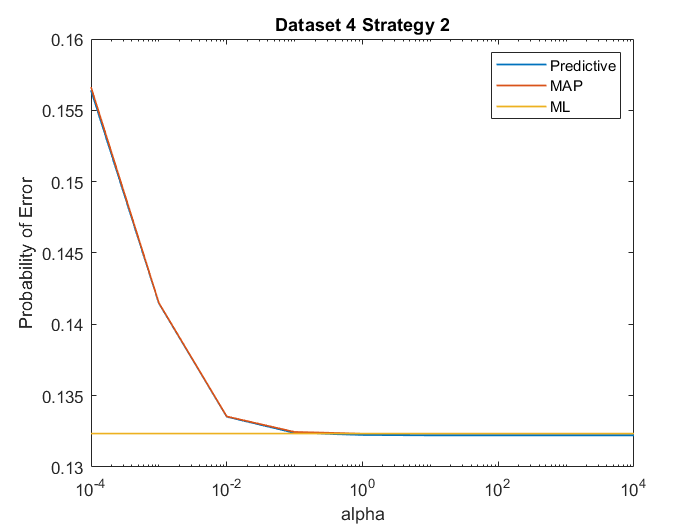

p_bbdr = zeros(2, 4, size(alpha, 2)); % Bayesian BDR
p_bmapbdr = zeros(2, 4, size(alpha, 2)); % Bayesian MAP BDR
p_mlbdr = zeros(2, 4, size(alpha, 2)); % ML BDR

for s = 1:2 % for each strategy
    if s == 1
        load("C:\Users\Muriate_C\Desktop\ECE 271A\HW3\hw3Data\Prior_1.mat")
    end
    if s == 2
        load("C:\Users\Muriate_C\Desktop\ECE 271A\HW3\hw3Data\Prior_2.mat")
    end
    
    for d = 1:4 % for each dataset
        s_bg = 1;
        s_fg = 1;
        for i = 1:d
            s_bg = s_bg + D_BG_index(1, i);
            s_fg = s_fg + D_FG_index(1, i);
        end
        s_bg;
        e_bg = s_bg + D_BG_index(1, d + 1) - 1;
        s_fg;
        e_fg = s_fg + D_FG_index(1, d + 1) - 1;
        D_BG = D_BG_all(s_bg:e_bg, :);
        D_FG = D_FG_all(s_fg:e_fg, :);
        
        % Compute the priors
        prob_bg = size(D_BG, 1) / (size(D_BG, 1) + size(D_FG, 1))
        prob_fg = size(D_FG, 1) / (size(D_BG, 1) + size(D_FG, 1))
        
        % Compute the covariance of the class-conditional - D1
        mean_bg = mean(D_BG, 1)
        cov_bg = 0;
        for i = 1:size(D_BG, 1)
            cov_bg = cov_bg + (D_BG(i, :) - mean_bg).'*(D_BG(i, :) - mean_bg)./size(D_BG, 1);
        end
        cov_bg
        
        mean_fg = mean(D_FG, 1)
        cov_fg = 0;
        for i = 1:size(D_FG, 1)
            cov_fg = cov_fg + (D_FG(i, :) - mean_fg).'*(D_FG(i, :) - mean_fg)./size(D_FG, 1);
        end
        cov_fg
        
        for j = 1:size(alpha, 2)
            %% Bayesian BDR
            % Compute the posterior mean and covariance
            mu_0_bg = mu0_BG;
            mu_0_fg = mu0_FG;
            Sigma_0 = zeros(64, 64);
            for i = 1:64
                Sigma_0(i, i) = alpha(1, j) * W0(1, i);
            end
            
            n_bg = size(D_BG, 1);
            n_fg = size(D_FG, 1);
            mu_n_bg = (Sigma_0*inv(Sigma_0+cov_bg/n_bg)*mean_bg.'+cov_bg*inv(Sigma_0+cov_bg/n_bg)*mu_0_bg.'/n_bg).';
            sigma_n_bg = Sigma_0*inv(Sigma_0+cov_bg/n_bg)/n_bg*cov_bg;
            mu_n_fg = (Sigma_0*inv(Sigma_0+cov_fg/n_fg)*mean_fg.'+cov_fg*inv(Sigma_0+cov_fg/n_fg)*mu_0_fg.'/n_fg).';
            sigma_n_fg = Sigma_0*inv(Sigma_0+cov_fg/n_fg)/n_fg*cov_fg;
            
            mask_bbdr = blockproc(img_scan, [1, 64], @(block_struct) BDR(block_struct.data, mu_n_bg, mu_n_fg, cov_bg+sigma_n_bg, cov_fg+sigma_n_fg, prob_bg, prob_fg));
            p_bbdr(s, d, j) = P_Error(ground_truth, mask_bbdr, prob_bg, prob_fg);
            
            %% Bayes MAP-BDR
            mask_bmapbdr = blockproc(img_scan, [1, 64], @(block_struct) BDR(block_struct.data, mu_n_bg, mu_n_fg, cov_bg, cov_fg, prob_bg, prob_fg));
            p_bmapbdr(s, d, j) = P_Error(ground_truth, mask_bmapbdr, prob_bg, prob_fg);
        end
        
        %% ML-BDR
        mask_mlbdr = blockproc(img_scan, [1, 64], @(block_struct) BDR(block_struct.data, mean_bg, mean_fg, cov_bg, cov_fg, prob_bg, prob_fg));
        p_mlbdr(s, d, :) = P_Error(ground_truth, mask_mlbdr, prob_bg, prob_fg);
        
        % Plot PoE
        f = figure((s-1)*4+d);
        slg = semilogx(alpha, reshape(p_bbdr(s, d, :), [1, 9]), alpha, reshape(p_bmapbdr(s, d, :), [1, 9]), alpha, reshape(p_mlbdr(s, d, :), [1, 9]));
        title(join(["Dataset", int2str(d), "Strategy", int2str(s)]))
        xlabel("alpha")
        ylabel("Probability of Error")
        legend('Predictive', 'MAP', 'ML')
        slg(1).LineWidth = 1;
        slg(2).LineWidth = 1;
        slg(3).LineWidth = 1;
        exportgraphics(f, append('d', int2str(d), 's', int2str(s), '.png'))
    end
end

p_bbdr

p_bbdr = p_bbdr(:,:,1) =

    0.1641    0.1176    0.1316    0.1257
    0.1719    0.1436    0.1640    0.1564


p_bbdr(:,:,2) =

    0.1645    0.1199    0.1342    0.1291
    0.1698    0.1328    0.1488    0.1415


p_bbdr(:,:,3) =

    0.1652    0.1228    0.1369    0.1316
    0.1664    0.1250    0.1393    0.1335


p_bbdr(:,:,4) =

    0.1653    0.1233    0.1373    0.1322
    0.1655    0.1237    0.1376    0.1324


p_bbdr(:,:,5) =

    0.1653    0.1235    0.1374    0.1322
    0.1653    0.1235    0.1374    0.1322


p_bbdr(:,:,6) =

    0.1653    0.1235    0.1374    0.1322
    0.1653    0.1235    0.1374    0.1322


p_bbdr(:,:,7) =

    0.1653    0.1235    0.1374    0.1322
    0.1653    0.1235    0.1374    0.1322


p_bbdr(:,:,8) =

    0.1653    0.1235    0.1374    0.1322
    0.1653    0.1235    0.1374    0.1322


p_bbdr(:,:,9) =

    0.1653    0.1235    0.1374    0.1322
    0.1653    0.1235    0.1374    0.1322


p_bmapbdr

p_bmapbdr = p_bmapbdr(:,:,1) =

    0.1651    0.1176    0.1318    0.1259
    0.1726    0.1436    0.1642    0.1566


p_bmapbdr(:,:,2) =

    0.1654    0.1198    0.1342    0.1292
    0.1703    0.1328    0.1489    0.1415


p_bmapbdr(:,:,3) =

    0.1659    0.1225    0.1369    0.1317
    0.1672    0.1249    0.1394    0.1335


p_bmapbdr(:,:,4) =

    0.1663    0.1232    0.1373    0.1322
    0.1665    0.1236    0.1375    0.1325


p_bmapbdr(:,:,5) =

    0.1663    0.1232    0.1373    0.1323
    0.1664    0.1232    0.1374    0.1323


p_bmapbdr(:,:,6) =

    0.1664    0.1232    0.1374    0.1323
    0.1664    0.1232    0.1374    0.1323


p_bmapbdr(:,:,7) =

    0.1664    0.1232    0.1374    0.1323
    0.1664    0.1232    0.1374    0.1323


p_bmapbdr(:,:,8) =

    0.1664    0.1232    0.1374    0.1323
    0.1664    0.1232    0.1374    0.1323


p_bmapbdr(:,:,9) =

    0.1664    0.1232    0.1374    0.1323
    0.1664    0.1232    0.1374    0.1323


p_mlbdr

p_mlbdr = p_mlbdr(:,:,1) =

    0.1664    0.1232    0.1374    0.1323
    0.1664    0.1232    0.1374    0.1323


p_mlbdr(:,:,2) =

    0.1664    0.1232    0.1374    0.1323
    0.1664    0.1232    0.1374    0.1323


p_mlbdr(:,:,3) =

    0.1664    0.1232    0.1374    0.1323
    0.1664    0.1232    0.1374    0.1323


p_mlbdr(:,:,4) =

    0.1664    0.1232    0.1374    0.1323
    0.1664    0.1232    0.1374    0.1323


p_mlbdr(:,:,5) =

    0.1664    0.1232    0.1374    0.1323
    0.1664    0.1232    0.1374    0.1323


p_mlbdr(:,:,6) =

    0.1664    0.1232    0.1374    0.1323
    0.1664    0.1232    0.1374    0.1323


p_mlbdr(:,:,7) =

    0.1664    0.1232    0.1374    0.1323
    0.1664    0.1232    0.1374    0.1323


p_mlbdr(:,:,8) =

    0.1664    0.1232    0.1374    0.1323
    0.1664    0.1232    0.1374    0.1323


p_mlbdr(:,:,9) =

    0.1664    0.1232    0.1374    0.1323
    0.1664    0.1232    0.1374    0.1323


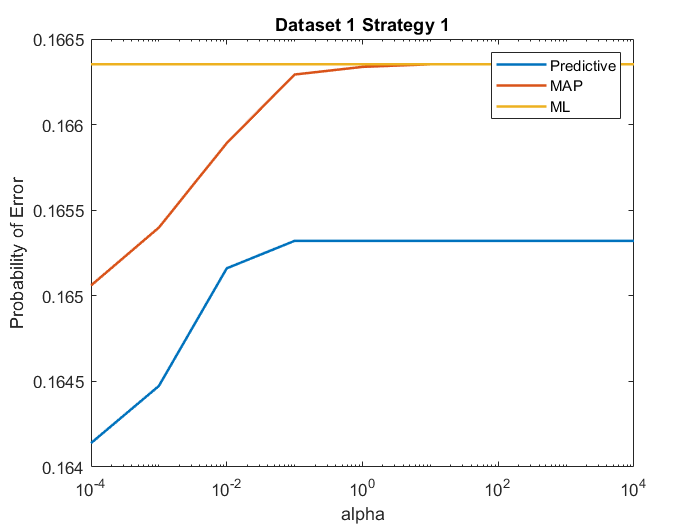

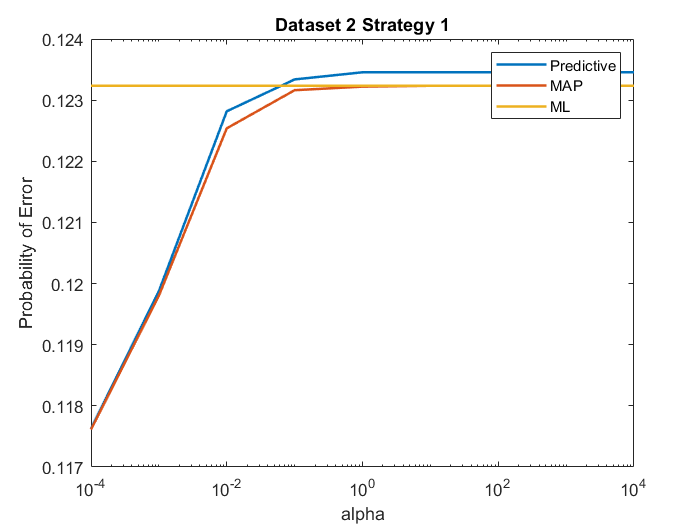

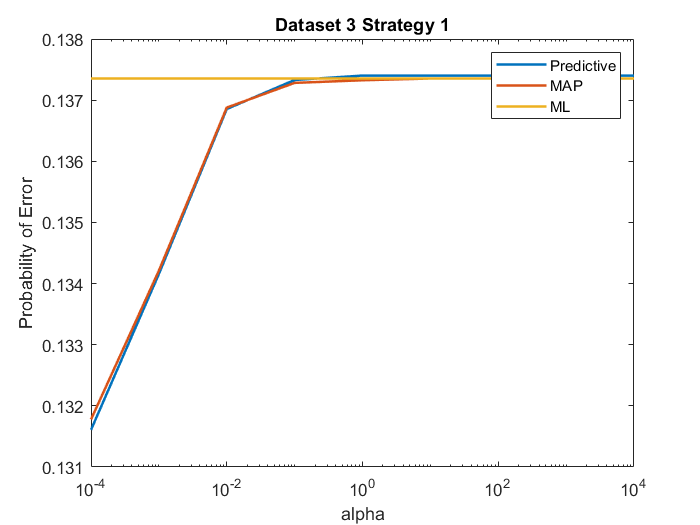

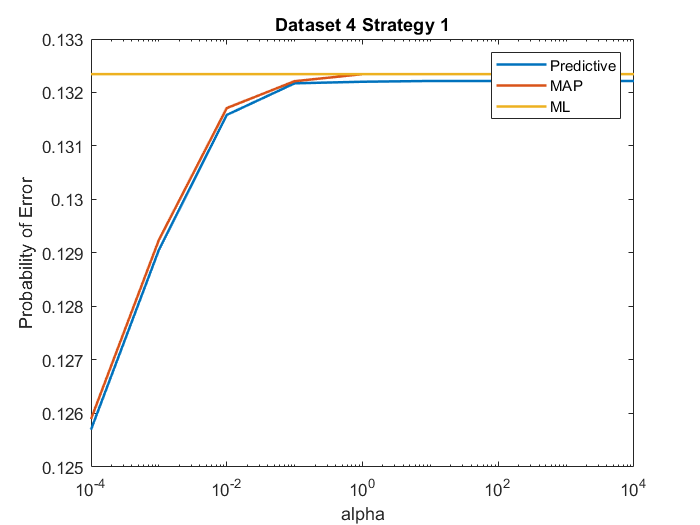

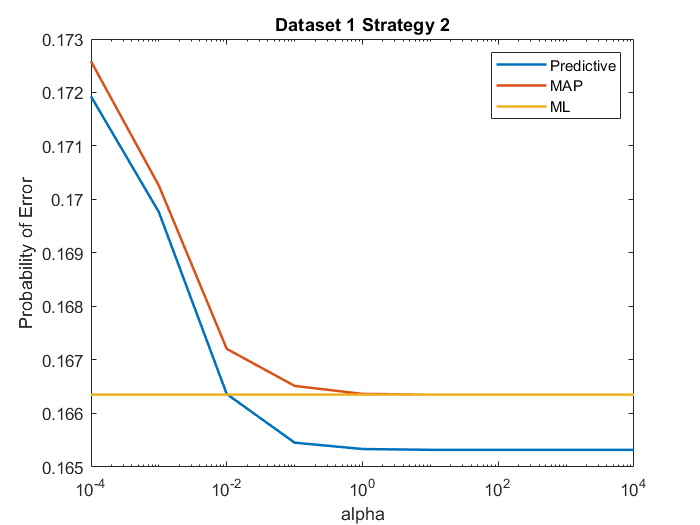

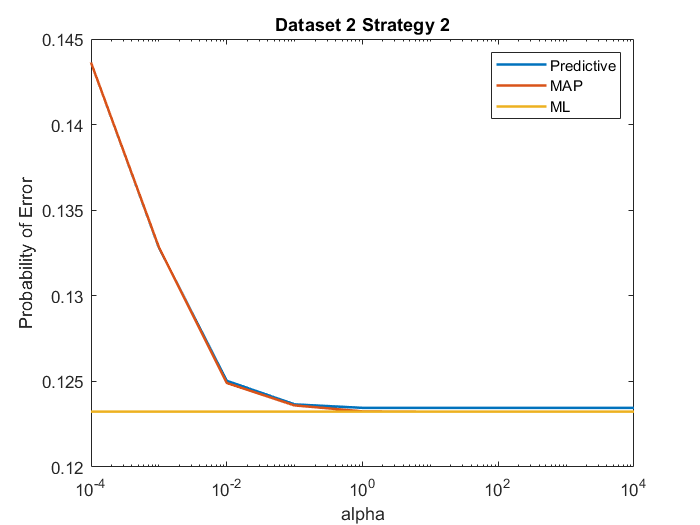

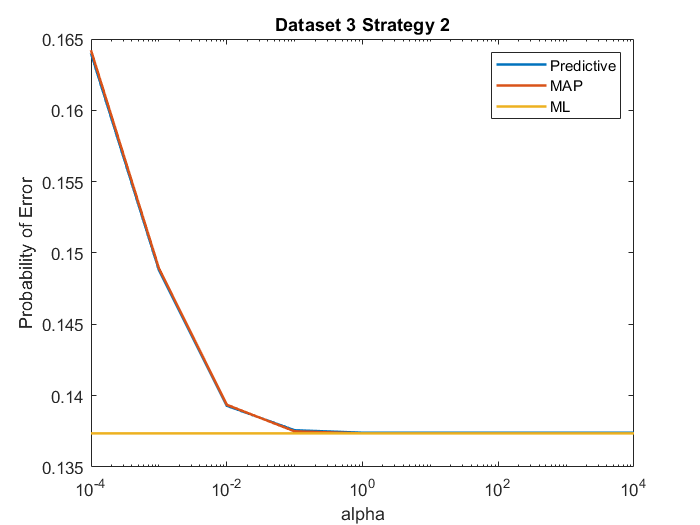

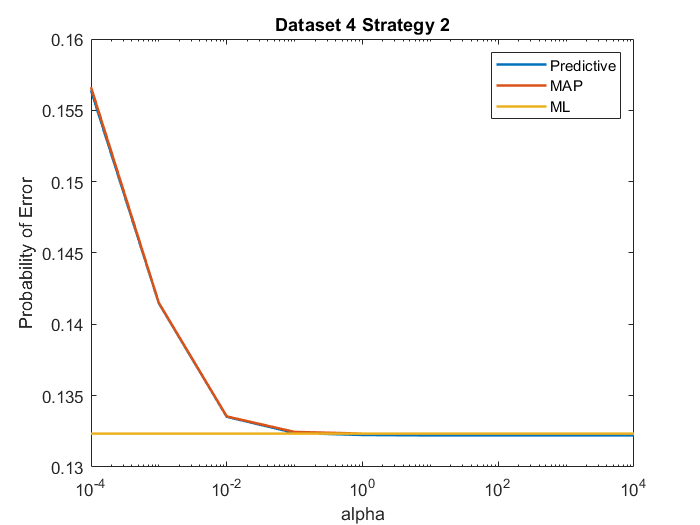

for s = 1:2
    for d = 1:4
        f = figure((s-1)*4+d);
        slg = semilogx(alpha, reshape(p_bbdr(s, d, :), [1, 9]), alpha, reshape(p_bmapbdr(s, d, :), [1, 9]), alpha, reshape(p_mlbdr(s, d, :), [1, 9]));
        title(join(["Dataset", int2str(d), "Strategy", int2str(s)]))
        xlabel("alpha")
        ylabel("Probability of Error")
        legend('Predictive', 'MAP', 'ML')
        slg(1).LineWidth = 1.5;
        slg(2).LineWidth = 1.5;
        slg(3).LineWidth = 1.5;
        exportgraphics(f, append('d', int2str(d), 's', int2str(s), '.png'))
    end
end

% % Plot PoE
% for d = 1:4
%     figure(d)
%     slg = semilogx(alpha, p_bbdr(d, :), alpha, p_bmapbdr(d, :), alpha, p_mlbdr(d, :));
%     title(join(["Dataset", int2str(d), "Strategy", 2]))
%     xlabel("alpha")
%     ylabel("Probability of Error")
%     legend('Predictive', 'MAP', 'ML')
%     slg(1).LineWidth = 1;
%     slg(2).LineWidth = 1;
%     slg(3).LineWidth = 1;
% end

% % Compute the priors
% prob_bg_1 = size(D1_BG, 1) / (size(D1_BG, 1) + size(D1_FG, 1))
% prob_fg_1 = size(D1_FG, 1) / (size(D1_BG, 1) + size(D1_FG, 1))

% % Compute the covariance of the class-conditional - D1
% mean_d1_bg = mean(D1_BG, 1)
% cov_d1_bg = 0;
% for i = 1:size(D1_BG, 1)
%     cov_d1_bg = cov_d1_bg + (D1_BG(i, :) - mean_d1_bg).'*(D1_BG(i, :) - mean_d1_bg)./size(D1_BG, 1);
% end
% cov_d1_bg
% 
% mean_d1_fg = mean(D1_FG, 1)
% cov_d1_fg = 0;
% for i = 1:size(D1_FG, 1)
%     cov_d1_fg = cov_d1_fg + (D1_FG(i, :) - mean_d1_fg).'*(D1_FG(i, :) - mean_d1_fg)./size(D1_FG, 1);
% end
% cov_d1_fg

% p_bbdr = zeros(1, size(alpha, 2));
% p_bmapbdr = zeros(1, size(alpha, 2));
% 
% for j = 1:size(alpha, 2)
%     %% Bayesian BDR
%     % Compute the posterior mean and covariance
%     mu_0_bg = mu0_BG;
%     mu_0_fg = mu0_FG;
%     Sigma_0 = zeros(64, 64);
%     for i = 1:64
%         Sigma_0(i, i) = alpha(1, j) * W0(1, i);
%     end
%     
%     n = 64;
%     mu_n_d1_bg = (Sigma_0*inv(Sigma_0+1/n*cov_d1_bg)*mean_d1_bg.'+1/n*cov_d1_bg*inv(Sigma_0+1/n*cov_d1_bg)*mu_0_bg.').';
%     sigma_n_bg = Sigma_0*inv(Sigma_0+1/n*cov_d1_bg)*1/n*cov_d1_bg;
%     mu_n_d1_fg = (Sigma_0*inv(Sigma_0+1/n*cov_d1_fg)*mean_d1_fg.'+1/n*cov_d1_fg*inv(Sigma_0+1/n*cov_d1_fg)*mu_0_fg.').';
%     sigma_n_fg = Sigma_0*inv(Sigma_0+1/n*cov_d1_fg)*1/n*cov_d1_fg;
%     
%     mask_bbdr = blockproc(img_scan, [1, 64], @(block_struct) BDR(block_struct.data, mu_n_d1_bg, mu_n_d1_fg, cov_d1_bg+sigma_n_bg, cov_d1_fg+sigma_n_fg, prob_bg_1, prob_fg_1));
%     p_bbdr(1, j) = P_Error(ground_truth, mask_bbdr, prob_bg_1, prob_fg_1)
%     
%     %% Bayes MAP-BDR
%     mask_bmapbdr = blockproc(img_scan, [1, 64], @(block_struct) BDR(block_struct.data, mu_n_d1_bg, mu_n_d1_fg, cov_d1_bg, cov_d1_fg, prob_bg_1, prob_fg_1));
%     p_bmapbdr(1, j) = P_Error(ground_truth, mask_bmapbdr, prob_bg_1, prob_fg_1)
% end

% % ML-BDR
% p_mlbdr = ones(1, size(alpha, 2));
% mask_mlbdr = blockproc(img_scan, [1, 64], @(block_struct) BDR(block_struct.data, mean_d1_bg, mean_d1_fg, cov_d1_bg, cov_d1_fg, prob_bg_1, prob_fg_1));
% p_mlbdr = P_Error(ground_truth, mask_mlbdr, prob_bg_1, prob_fg_1) * p_mlbdr;

function vector = ZigZagScan(matrix, pattern)
    vector = zeros(1, size(matrix, 1) * size(matrix, 2));
    for i = 1:size(matrix, 1)
        for j = 1:size(matrix, 2)
            position = pattern(i, j);
            vector(1, position) = matrix(i, j);
        end
    end
end

function mask = BDR(feature, mu_bg, mu_fg, sigma_bg, sigma_fg, P_bg, P_fg)
    if (feature-mu_bg)*inv(sigma_bg)*(feature-mu_bg).'+log((2*pi).^64*det(sigma_bg))-2*log(P_bg)...
            < (feature-mu_fg)*inv(sigma_fg)*(feature-mu_fg).'+log((2*pi).^64*det(sigma_fg))-2*log(P_fg)
        mask = 0;
    else
        mask = 1;
    end
end

function dct = dct_8(img, img_pad)
    dct = zeros(size(img, 1) * 8, size(img, 2) * 8);
    for i = 1:size(img, 1)
        for j = 1:size(img, 2)
            dct((8*i-7):(8*i), (8*j-7):(8*j)) = dct2(img_pad(i:i+7, j:j+7));
        end
    end
end

function p = P_Error(gt, mask, prob_bg, prob_fg)
    gt = int8(gt);
    mask = int8(mask);
    diff = gt - mask;
    detect = 1 - sum(sum(diff==1))/sum(sum(gt==1));
    fAlarm = sum(sum(diff==-1))/sum(sum(gt==0));
    p = fAlarm * prob_bg + (1 - detect) * prob_fg;
end